# Preparación parcial: (s+3)/(s^3+3s^2+10s+3)

comp=tf('s');
num=[1 3];
den=[1 0 2 10];
fdt=tf(num,den)

fdt =
 
      s + 3
  --------------
  s^3 + 2 s + 10
 
Continuous-time transfer function.



[matrizA,matrizB,matrizC,matrizD] = tf2ss(num,den);
A=matrizA

A =      0    -2   -10
     1     0     0
     0     1     0


B=matrizB

B =      1
     0
     0


C=matrizC

C =      0     1     3


D=matrizD

D = 0

%%%%%%%Determinacion de controlabilidad y observabilidad%%%%%%
M=[B,A-B,A^2*B]

M =      1    -1    -3   -11    -2
     0     1     0     0     0
     0     0     1     0     1


N=[C;C*A;C*A^2]

N =      0     1     3
     1     3     0
     3    -2   -10


n=rank(A)

n = 3

RM= rank(M)

RM = 3

RN= rank(N)

RN = 3

if RM==n
    controlable=1
else
    controlable=0
end

controlable = 1

if RN==n
    observable=1
else
    observable=0
end

observable = 1

## *Punto 1: PID discreto*

Gct1 = pidtune(fdt,'PID') %Usar pidtool

Gct1 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 79.1, Ki = 63.3, Kd = 24.7
 
Continuous-time PID controller in parallel form.



Hd = c2d(fdt,0.0001,'foh')

Hd =
 
                                
  1.667e-09 z^3 + 5.001e-09 z^2 
                                
          - 4.999e-09 z         
                                
                    - 1.667e-09 
                                
  ------------------------------
                           
      z^3 - 3 z^2 + 3 z - 1
                           
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



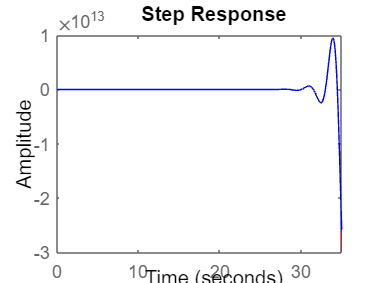

step(fdt,'-r',Hd,'b')

## *Punto 2: Diseñar retro con observador*

%U vector
zitaobser = 1;
tsobser = 0.0429; %Debe ser 10 veces menor al del controlador 
wno = 4/(zitaobser*tsobser);
podeseadoobserva = [1 2*zitaobser*wno wno^2];
phiAtob = podeseadoobserva(1)*(A')^2+...
    podeseadoobserva(2)*(A')+...
    podeseadoobserva(3)*eye(n);
Ninv=(N^(-1));
ke = phiAtob*Ninv*[0;0;1]

ke = 1.0e+03 *

    3.3768
   -1.2754
   -0.3504



%Integrador adicional
zitadesecont = 1;
tsdesecont = 0.1;
wndcont = 4/(zitadesecont*tsdesecont);
Aempa = [A,[0;0;0]; -C,0]

Aempa =      0    -2   -10     0
     1     0     0     0
     0     1     0     0
     0    -1    -3     0


Bempa = [B;0]

Bempa =      1
     0
     0
     0


pdeseadocontrolador = conv([1 2*zitadesecont*wndcont wndcont^2],...
    [1 (200*zitadesecont*wndcont)])

pdeseadocontrolador =            1        8080      641600    12800000


pdeseadocontrolador1=conv(pdeseadocontrolador,...
    [1 (200*zitadesecont*wndcont)])

pdeseadocontrolador1 = 1.0e+11 *

    0.0000    0.0000    0.0007    0.0515    1.0240


phiAemp=(Aempa^4)+pdeseadocontrolador1(2)*(Aempa^3)+...
    pdeseadocontrolador1(3)*(Aempa^2)+...
    pdeseadocontrolador1(4)*(Aempa)+pdeseadocontrolador1(5)*eye(4)

phiAemp = 1.0e+11 *

    1.0227   -0.1094   -0.5146         0
    0.0515    1.0227   -0.0065         0
    0.0007    0.0515    1.0240         0
   -0.0007   -0.0534   -0.1544    1.0240



kemp = [0 0 0 1]*inv([Bempa Aempa*Bempa (Aempa^2)*Bempa (Aempa^3)*Bempa])*phiAemp

kemp = 1.0e+10 *

    0.0000    0.0065   -2.8988   -3.4133



k12 = [kemp(1:3)]

k12 = 1.0e+10 *

    0.0000    0.0065   -2.8988


ki = -kemp(4)

ki = 3.4133e+10

## Punto 3: Diseñar retro discreto con observador

zitadesecontdis=0.7;
tssdesecontdis=1;
wdcontdis=4/(zitadesecontdis*tssdesecontdis);
ws=20*wdcontdis

ws = 114.2857

TM=(2*pi)/ws

TM = 0.0550


[m,n]=size(A)

m = 3

n = 3


syms z s t
G1=(s*eye(n)-A)

$$G1 = \left(\begin{array}{ccc} s & 2 & 10\\ -1 & s & 0\\ 0 & -1 & s \end{array}\right)$$

G2= inv(G1)

$$G2 = \begin{array}{l} \left(\begin{array}{ccc} \frac{s^{2}}{\sigma_{1}} & -\frac{2\,\left(s+5\right)}{\sigma_{1}} & -\frac{10\,s}{\sigma_{1}}\\ \frac{s}{\sigma_{1}} & \frac{s^{2}}{\sigma_{1}} & -\frac{10}{\sigma_{1}}\\ \frac{1}{\sigma_{1}} & \frac{s}{\sigma_{1}} & \frac{s^{2}+2}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s^{3}+2\,s+10 \end{array}$$

GT= ilaplace(G2)

$$GT = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & -10\,\sigma_{3}-2\,\sigma_{1} & -10\,\sigma_{1}\\ \sigma_{1} & \sigma_{2} & -10\,\sigma_{3}\\ \sigma_{3} & \sigma_{1} & 2\,\sigma_{3}+\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)\,t}\,\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}{3\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}+2}\\ \sigma_{2}=\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}}{3\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}+2}\\ \sigma_{3}=\sum_{k=1}^{3}\frac{{\mathrm{e}}^{t\,\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}}{3\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}+2} \end{array}$$

G3=(subs(GT,t,TM)) %% Matriz A

$$G3 = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & -10\,\sigma_{3}-2\,\sigma_{1} & -10\,\sigma_{1}\\ \sigma_{1} & \sigma_{2} & -10\,\sigma_{3}\\ \sigma_{3} & \sigma_{1} & 2\,\sigma_{3}+\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\frac{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)\,\pi \,7}{400}}\,\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}{3\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}+2}\\ \sigma_{2}=\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\frac{7\,\pi \,\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}{400}}\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}}{3\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}+2}\\ \sigma_{3}=\sum_{k=1}^{3}\frac{{\mathrm{e}}^{\frac{7\,\pi \,\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}{400}}}{3\,{\mathrm{root}\left(z^{3}+2\,z+10,z,k\right)}^{2}+2} \end{array}$$

G=vpa(G3)

$$G = \left(\begin{array}{ccc} 0.99670217011190507750784209294196 & -0.12494218496371504792067823889179 & -0.54918691692393149987505862390748\\ 0.054918691692393149987505862390748 & 0.99670217011190507750784209294196 & -0.015104801578928747945666514110294\\ 0.0015104801578928747945666514110294 & 0.054918691692393149987505862390748 & 0.99972313042769082709697539576401 \end{array}\right)$$

H=vpa(int(GT,0,TM)*B) %% Matriz B

$$H = \left(\begin{array}{c} 0.054918691692393149987505862390748\\ 0.0015104801578928747945666514110294\\ 0.000027686957230917290302460423598534 \end{array}\right)$$

%%%%%%% Determinacion de controlabilidad y observabilidad %%%%%%
Md=[H,G*H,G^2*H]

$$Md = \left(\begin{array}{ccc} 0.054918691692393149987505862390748 & 0.054533651183562780245096807841664 & 0.053682611789064191019493441581558\\ 0.0015104801578928747945666514110294 & 0.0045211433424916364309935981122731 & 0.0074982260716939764072720523469428\\ 0.000027686957230917290302460423598534 & 0.00019358647975250245679331838560185 & 0.00052420015692028544149061449261678 \end{array}\right)$$

Nd=[C;C*G;C*G^2]

$$Nd = \left(\begin{array}{ccc} 0 & 1 & 3\\ 0.059450132166071774371205816623836 & 1.1614582451890845274703596801142 & 2.9840645897041437333452596731817\\ 0.12754721337710946390928341880232 & 1.3140810472572645707757297235586 & 2.933045561886652295331524140491 \end{array}\right)$$

n= rank(G)

n = 3

RM= rank(Md)

RM = 3

RN= rank(Nd)

RN = 3

if RM==n
    controlable=1
else
    controlable=0
end

controlable = 1

if RN==n
    observable=1
else
    observable=0
end

observable = 1


magpolodeseado=exp(((2*pi*zitadesecontdis)/...
    sqrt(1-zitadesecontdis^2))*(wdcontdis/ws))

magpolodeseado = 1.3606


angdeseado= 2*pi*(wdcontdis/ws)

angdeseado = 0.3142


[real,imag] =pol2cart(magpolodeseado,angdeseado)

real = 0.0655

imag = 0.3072

polodeseado=real+i*imag

polodeseado = 0.0655 + 0.3072i

polodeseadoconj=real-i*imag

polodeseadoconj = 0.0655 - 0.3072i

pdeseadocontroladordis=conv(conv(conv([1 -polodeseado],[1 -polodeseadoconj]),...
    [1 0.0005]),[1 0.0005])

pdeseadocontroladordis =     1.0000   -0.1301    0.0986    0.0001    0.0000


Gempa=[G, [0;0;0];C*G,1]

$$Gempa = \left(\begin{array}{cccc} 0.99670217011190507750784209294196 & -0.12494218496371504792067823889179 & -0.54918691692393149987505862390748 & 0\\ 0.054918691692393149987505862390748 & 0.99670217011190507750784209294196 & -0.015104801578928747945666514110294 & 0\\ 0.0015104801578928747945666514110294 & 0.054918691692393149987505862390748 & 0.99972313042769082709697539576401 & 0\\ 0.059450132166071774371205816623836 & 1.1614582451890845274703596801142 & 2.9840645897041437333452596731817 & 1 \end{array}\right)$$

Hempa= [H; C*H]

$$Hempa = \left(\begin{array}{c} 0.054918691692393149987505862390748\\ 0.0015104801578928747945666514110294\\ 0.000027686957230917290302460423598534\\ 0.001593541029585626665474032681825 \end{array}\right)$$


phiGemp=(Gempa^4)+pdeseadocontroladordis(2)*...
    (Gempa^3)+pdeseadocontroladordis(3)*...
    (Gempa^2)+pdeseadocontroladordis(4)*...
    (Gempa)+pdeseadocontroladordis(5)*eye(4)

$$phiGemp = \left(\begin{array}{cccc} 0.90614521914145876269065949493895 & -0.63775608891553153380476313329238 & -2.0498720010840090253308170164944 & 0\\ 0.20498720010840090253308170164944 & 0.90614521914145876269065949493895 & -0.2277816886987297287385997299935 & 0\\ 0.02277816886987297287385997299935 & 0.20498720010840090253308170164944 & 0.95170155688120470843837944093764 & 0\\ 0.64557680104426192953835840928386 & 5.2439731860674496536390456113562 & 10.911138927611625297158573647433 & \frac{146366760952218783472699}{151115727451828646838272} \end{array}\right)$$

kempdis=[0 0 0 1]*inv([Hempa Gempa*Hempa (Gempa^2)*Hempa (Gempa^3)*Hempa])*phiGemp

$$kempdis = \left(\begin{array}{cccc} 28.225705605704297418322150690404 & -77.588437200207966101124418489924 & -24109.455036071326213707382005893 & 1943.8670974345369085515410977633 \end{array}\right)$$

k13dis=kempdis(1:3)

$$k13dis = \left(\begin{array}{ccc} 28.225705605704297418322150690404 & -77.588437200207966101124418489924 & -24109.455036071326213707382005893 \end{array}\right)$$

kidis=kempdis(4)

$$kidis = 1943.8670974345369085515410977633$$


%%%%%%%%%%%% Observador de estados en discreto %%%%%%%%%%%%%%%%%%
k13ev=eval(k13dis)

k13ev = 1.0e+04 *

    0.0028   -0.0078   -2.4109


kiev=eval(kidis)

kiev = 1.9439e+03

H1= eval(H)

H1 =     0.0549
    0.0015
    0.0000


polinomiodeseaobservadis=z^(n)

$$polinomiodeseaobservadis = z^{3}$$

phiGobser=G^(n)

$$phiGobser = \left(\begin{array}{ccc} 0.96548556491680597284847146324134 & -0.46156840505082511883251524233039 & -1.6313495466502012125209611181397\\ 0.16313495466502012125209611181397 & 0.96548556491680597284847146324134 & -0.13529849572078487632832301870245\\ 0.013529849572078487632832301870245 & 0.16313495466502012125209611181397 & 0.99254526406096294811413606698183 \end{array}\right)$$

Ninvv=(Nd^(-1))

$$Ninvv = \left(\begin{array}{ccc} 134.8692396210734520643493457684 & -264.44845979047387801426559163179 & 131.10044071459697376126909980776\\ -54.042571742955021849135931429637 & 100.26678065948896977010577275578 & -46.734642053284791642449709327094\\ 18.347523914318340616378643809879 & -33.42226021982965659003525758526 & 15.578214017761597214149903109031 \end{array}\right)$$

kedis = eval(phiGobser*Ninvv*[0;0;1])

kedis =   122.7333
  -25.8423
    9.6118


Gev=eval(G)

Gev =     0.9967   -0.1249   -0.5492
    0.0549    0.9967   -0.0151
    0.0015    0.0549    0.9997


## *Punto 4: Diseñar compensador lead-led*

## *MP=70° y Oshoot=10%*

% sisotool(fdt) %Programa para hacer el compensador
% Value:  
%   18951 (s+1)^3 (s+0.8032) (s+10)^2
%   ---------------------------------
%      (s+248.4) (s+10)^2 (s+1)^3
num1=18951*(s+1)^3*(s+0.8032)*(s+10)^2;
den1=(s+248.4)*(s+10)^2*(s+1)^3;
comp=num1/den1

$$comp = \frac{18951\,\left(s+\frac{502}{625}\right)}{s+\frac{1242}{5}}$$

comp1=eval(comp)

$$comp1 = \frac{18951\,s+\frac{9513402}{625}}{s+\frac{1242}{5}}$$

gc=tf([18951 (9513402/625)],[1 (1242/5)])

gc =
 
  18951 s + 1.522e04
  ------------------
      s + 248.4
 
Continuous-time transfer function.

